a) Write down the gradient in closed form.

syms x y z
f1(x,y) = 2*x + 3*y + 1;
f2(x,y) = x^2 + y^2 - x*y - 5;
f3(x,y) = (x - 5)*cos(y-5) - (y - 5)*sin(x - 5);
grad1 = gradient(f1,[x,y])

$$grad1(x, y) = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

grad2 = gradient(f2,[x,y])

$$grad2(x, y) = \left(\begin{array}{c} 2\,x-y\\ 2\,y-x \end{array}\right)$$

grad3 = gradient(f3,[x,y])

$$grad3(x, y) = \left(\begin{array}{c} \cos\left(y-5\right)-\cos\left(x-5\right)\,\left(y-5\right)\\ -\sin\left(x-5\right)-\sin\left(y-5\right)\,\left(x-5\right) \end{array}\right)$$

b) Produce 2-D contour plot for each function.

For f1:

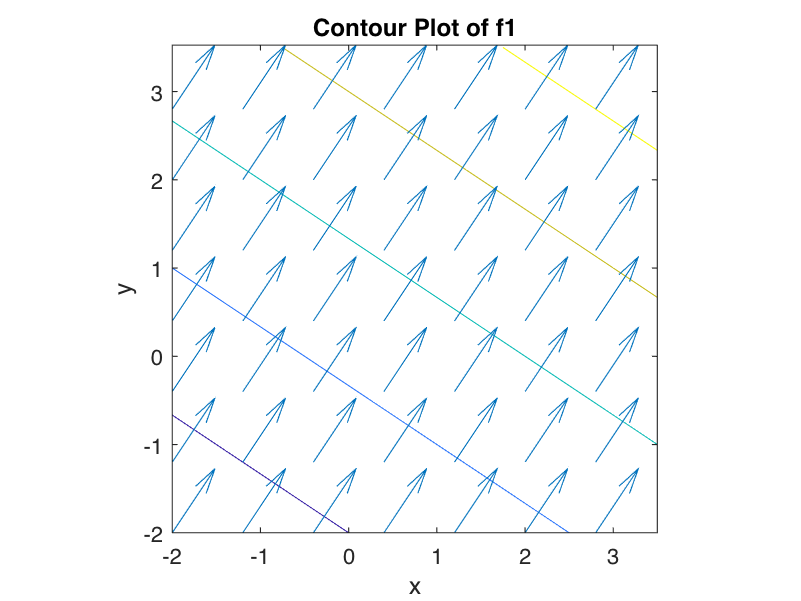

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f1(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = 2*X + 3*Y + 1;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f1');


%compute gradient at (1,0)
disp("Gradient at (1,0):")

Gradient at (1,0):


grad1(1,0)

$$ans = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

For f2:

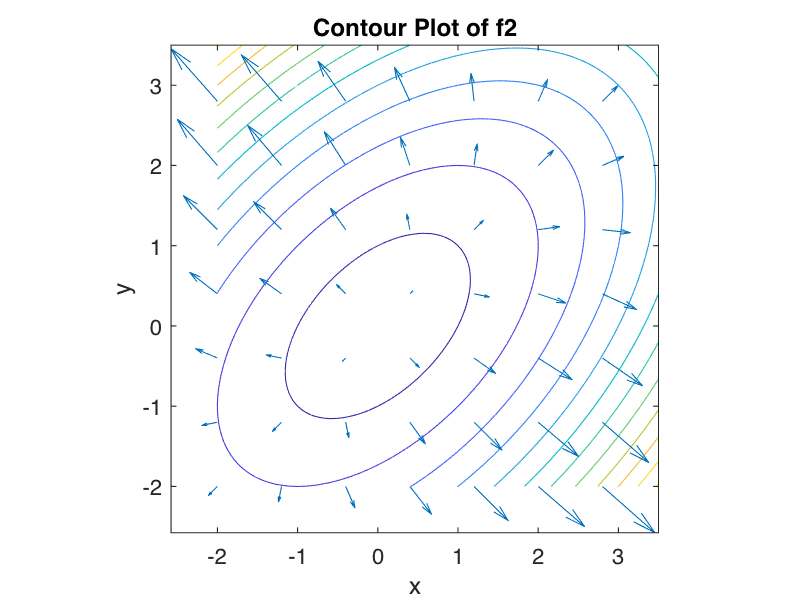

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f2(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2 - X.*Y - 5;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f2');


%compute gradient at (1,0)
disp("Gradient at (1,0):")

Gradient at (1,0):


grad2(1,0)

$$ans = \left(\begin{array}{c} 2\\ -1 \end{array}\right)$$

For f3:

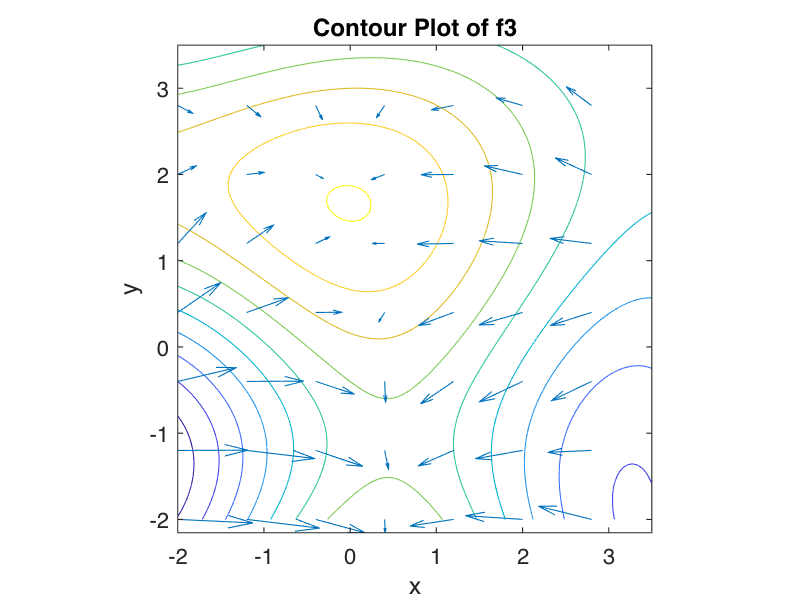

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f3(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = (X-Y).*cos(Y-5)-(Y-5).*sin(X-5);
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f3');


%compute gradient at (1,0)
disp("Gradient at (1,0):")

Gradient at (1,0):


grad3(1,0)

$$ans = \left(\begin{array}{c} 5\,\cos\left(4\right)+\cos\left(5\right)\\ \sin\left(4\right)-4\,\sin\left(5\right) \end{array}\right)$$

c) Plot 3-D linear approximation

For f1:

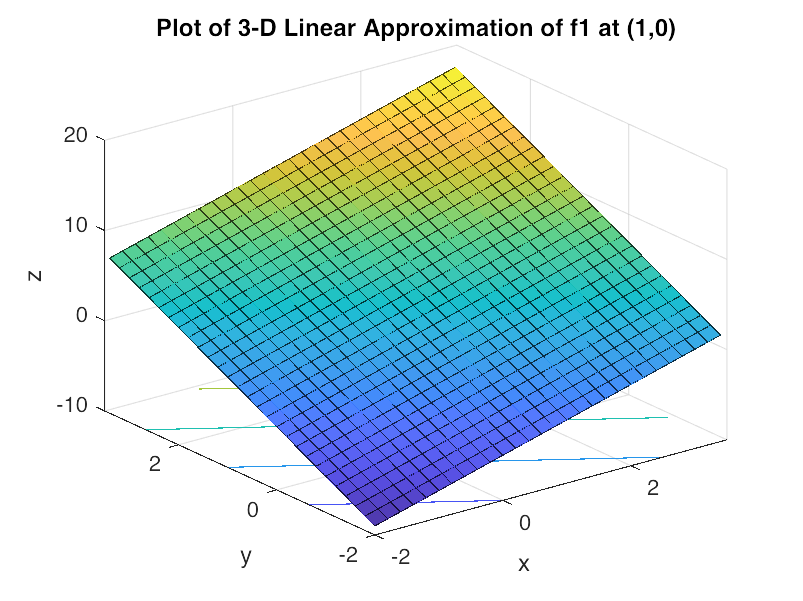

f1 = @(x,y) 2.*x + 3.*y + 1;

spacing = 0.2;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f1(X,Y),spacing);

x0 = 1;
y0 = 0;
t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

%compute tangent plane
f_approx = @(x,y) f1(x0,y0) + fx0*(x-x0) + fy0*(y-y0);
surf(X,Y,f_approx(X,Y),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f1(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Linear Approximation of f1 at (1,0)');

For f2:

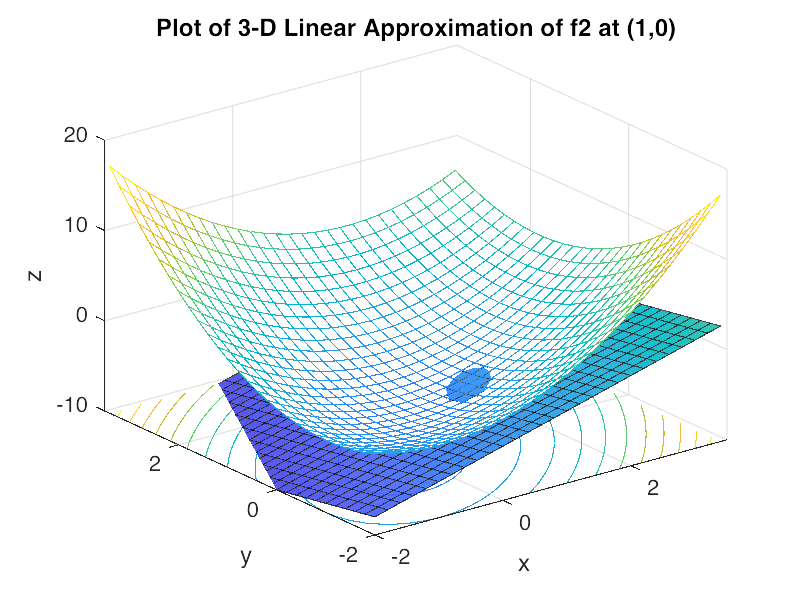

f2 = @(x,y) x.^2 + y.^2 - x.*y - 5;

spacing = 0.2;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f2(X,Y),spacing);

x0 = 1;
y0 = 0;
t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

%compute tangent plane
f_approx = @(x,y) f2(x0,y0) + fx0*(x-x0) + fy0*(y-y0);
surf(X,Y,f_approx(X,Y),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f2(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Linear Approximation of f2 at (1,0)');

For f3:

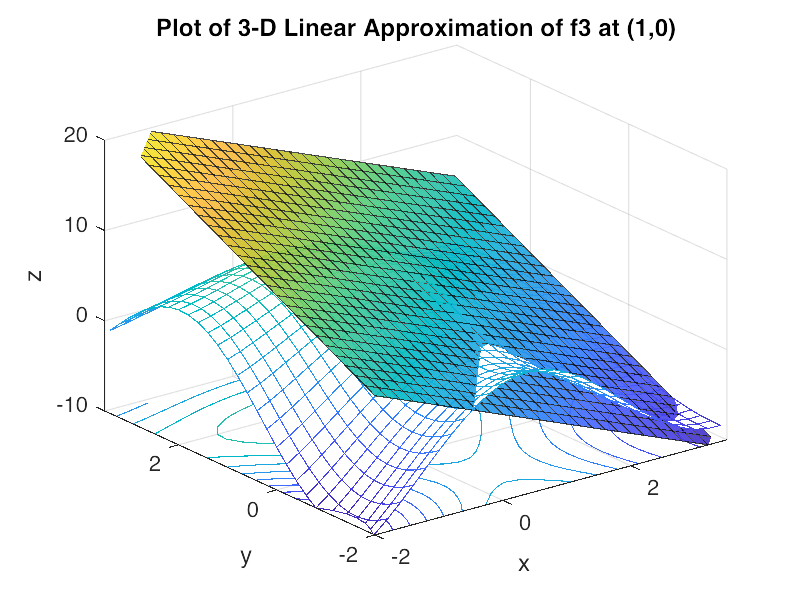

f3 = @(x,y) (x-5).*cos(y-5)-(y-5).*sin(x-5);

spacing = 0.2;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f3(X,Y),spacing);

x0 = 1;
y0 = 0;
t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

%compute tangent plane
f_approx = @(x,y) f3(x0,y0) + fx0*(x-x0) + fy0*(y-y0);
surf(X,Y,f_approx(X,Y),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f3(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Linear Approximation of f3 at (1,0)');